# Explicit MGRIT method comparison

## Setup variables

Q = 1;
h = 0.1;
dt = 0.001;
x = 0:h:1;
l = length(x);
N = 40;
T = zeros(1, l*N);
fc_ratio = 2;
level = 3;
iter = 15;

## Example 1: Stable example

### Original MGRIT explicit method

#### Plot MGRIT explicit result by iteration

figure
sgtitle('Direct explicit MGRIT implementation')
subplot(2,1,1)
title('Result at time T')
hold on
subplot(2,1,2)
title('Results for all time steps')
hold on

for i = 1:iter
    T = MGRIT_explicit(T, Q, h, dt, N, fc_ratio, level);
    subplot(2,1,1)
    plot(x, T(l*(N-1) + 1:l*N));
    subplot(2,1,2)
    plot(linspace(0, N, l*N), T);
end

#### Plot explicit time marching result

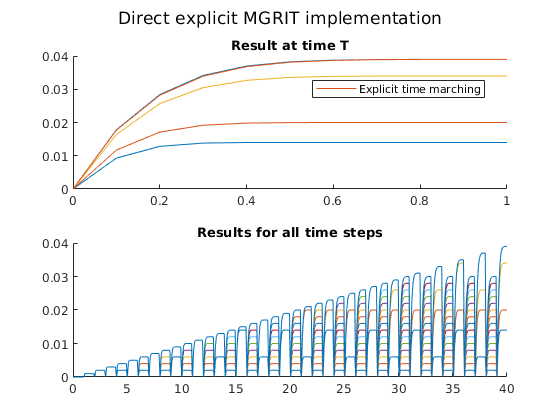

T_ETM = zeros(size(x));
for i = 1:N-1
    T_ETM = explicit_time_marching(T_ETM, Q, h, dt);
end
subplot(2,1,1)
p_ETM = plot(x, T_ETM); M1 = 'Explicit time marching';
legend(p_ETM, M1, 'Location', 'best');

### Method 1

To prevent exceeding CFL condition, use coarser x-grid on coarser time grids.

#### Plot MGRIT explicit result by iteration

T = zeros(1, l*N);
figure
sgtitle('Explicit MGRIT implementation with coarse x-grid')
subplot(2,1,1)
title('Result at time T')
hold on
subplot(2,1,2)
title('Results for all time steps')
hold on

for i = 1:iter
    T = MGRIT_explicit_method1(T, Q, h, dt, N, fc_ratio, level);
    subplot(2,1,1)
    plot(x, T(l*(N-1) + 1:l*N));
    subplot(2,1,2)
    plot(linspace(0, N, l*N), T);
end

#### Plot explicit time marching result

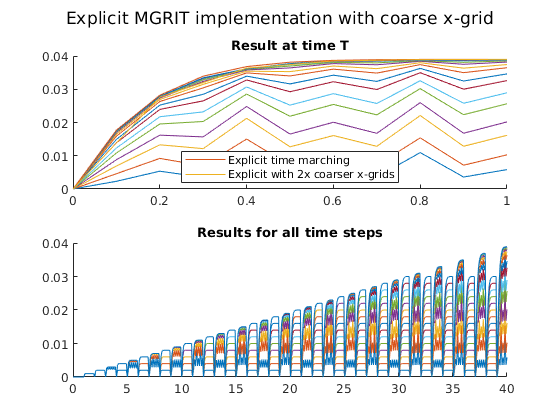

T_ETM = zeros(size(x));
for i = 1:N-1
    T_ETM = explicit_time_marching(T_ETM, Q, h, dt);
end
subplot(2,1,1)
p_ETM = plot(x, T_ETM); M1 = 'Explicit time marching';
legend(p_ETM, M1);

%% Plot with 2x coarse x-grid
h = 0.2;
x = 0:h:1;
T_2 = zeros(size(x));
for i = 1:N-1
    T_2 = explicit_time_marching(T_2, Q, h, dt);
end
p_2 = plot(x, T_2); M2 = 'Explicit with 2x coarser x-grids';
legend([p_ETM; p_2], M1, M2, 'Location', 'best');

## Example 2: Unstable example

Q = 1;
h = 0.1;
dt = 0.004;
x = 0:h:1;
l = length(x);
N = 40;
T = zeros(1, l*N);
fc_ratio = 2;
level = 3;
iter = 10;

### Original explicit MGRIT method

#### Plot MGRIT explicit result by iteration

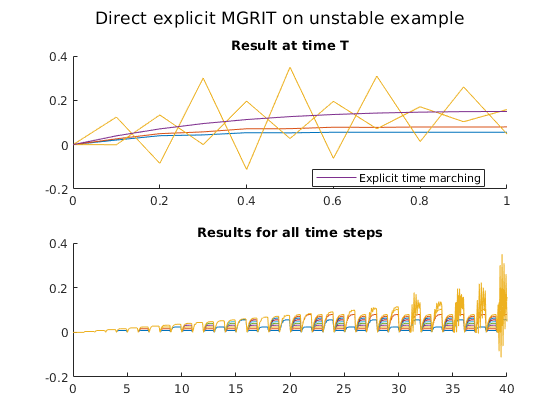

figure
sgtitle('Direct explicit MGRIT on unstable example')
subplot(2,1,1)
title('Result at time T')
hold on
subplot(2,1,2)
title('Results for all time steps')
hold on

for i = 1:iter
    T = MGRIT_explicit(T, Q, h, dt, N, fc_ratio, level);
    subplot(2,1,1)
    plot(x, T(l*(N-1) + 1:l*N));
    subplot(2,1,2)
    plot(linspace(0, N, l*N), T);
end
T_ETM = zeros(size(x));
for i = 1:N-1
    T_ETM = explicit_time_marching(T_ETM, Q, h, dt);
end
subplot(2,1,1)
p_ETM = plot(x, T_ETM); M1 = 'Explicit time marching';
legend(p_ETM, M1, 'Location', 'best');

### Method 1

To prevent exceeding CFL condition, use coarser x-grid on coarser time grids.

#### Plot MGRIT explicit result by iteration

T = zeros(1, l*N);
figure
sgtitle('Explicit MGRIT with coarse x-grid on unstable example')
subplot(2,1,1)
title('Result at time T')
hold on
subplot(2,1,2)
title('Results for all time steps')
hold on

for i = 1:iter
    T = MGRIT_explicit_method1(T, Q, h, dt, N, fc_ratio, level);
    subplot(2,1,1)
    plot(x, T(l*(N-1) + 1:l*N));
    subplot(2,1,2)
    plot(linspace(0, N, l*N), T);
end

#### Plot explicit time marching result

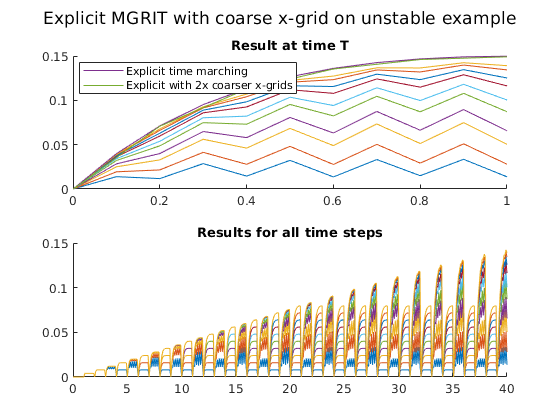

T_ETM = zeros(size(x));
for i = 1:N-1
    T_ETM = explicit_time_marching(T_ETM, Q, h, dt);
end
subplot(2,1,1)
p_ETM = plot(x, T_ETM); M1 = 'Explicit time marching';
legend(p_ETM, M1);

%% Plot with 2x coarse x-grid
h = 0.2;
x = 0:h:1;
T_2 = zeros(size(x));
for i = 1:N-1
    T_2 = explicit_time_marching(T_2, Q, h, dt);
end
p_2 = plot(x, T_2); M2 = 'Explicit with 2x coarser x-grids';
legend([p_ETM; p_2], M1, M2, 'Location', 'best');

### Method 2

Every time update only by 1 fine time step for all coarse grid operation.

#### Plot MGRIT explicit result by iteration

h = 0.1;
x = 0:h:1;
l = length(x);
T = zeros(1, l*N);
iter = 20;
figure
sgtitle('Explicit MGRIT with small update on unstable example')
subplot(2,1,1)
title('Result at time T')
hold on
subplot(2,1,2)
title('Results for all time steps')
hold on

for i = 1:iter
    T = MGRIT_explicit_method2(T, Q, h, dt, N, fc_ratio, level);
    subplot(2,1,1)
    plot(x, T(l*(N-1) + 1:l*N));
    subplot(2,1,2)
    plot(linspace(0, N, l*N), T);
end

#### Plot explicit time marching result

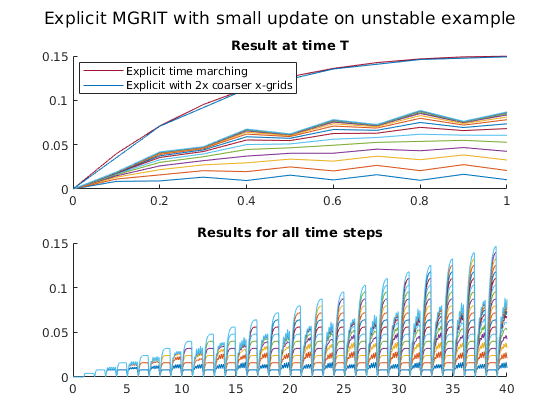

T_ETM = zeros(size(x));
for i = 1:N-1
    T_ETM = explicit_time_marching(T_ETM, Q, h, dt);
end
subplot(2,1,1)
p_ETM = plot(x, T_ETM); M1 = 'Explicit time marching';
legend(p_ETM, M1);

%% Plot with 2x coarse x-grid
h = 0.2;
x = 0:h:1;
T_2 = zeros(size(x));
for i = 1:N-1
    T_2 = explicit_time_marching(T_2, Q, h, dt);
end
p_2 = plot(x, T_2); M2 = 'Explicit with 2x coarser x-grids';
legend([p_ETM; p_2], M1, M2, 'Location', 'best');

### Method 3

Do explicit MGRIT with Method 1 error upperbound.

#### Plot MGRIT explicit result by iteration

h = 0.1;
x = 0:h:1;
l = length(x);
T = zeros(1, l*N);
iter = 20;
figure
sgtitle('Explicit MGRIT with upperbound on unstable example')
subplot(2,1,1)
title('Result at time T')
hold on
subplot(2,1,2)
title('Results for all time steps')
hold on

for i = 1:iter
    T = MGRIT_explicit_method3(T, Q, h, dt, N, fc_ratio, level);
    subplot(2,1,1)
    plot(x, T(l*(N-1) + 1:l*N));
    subplot(2,1,2)
    plot(linspace(0, N, l*N), T);
end

#### Plot explicit time marching result

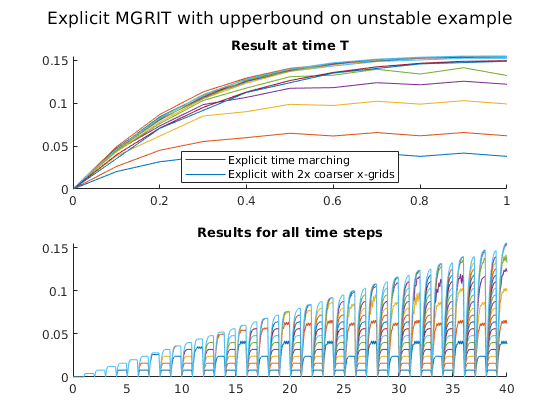

T_ETM = zeros(size(x));
for i = 1:N-1
    T_ETM = explicit_time_marching(T_ETM, Q, h, dt);
end
subplot(2,1,1)
p_ETM = plot(x, T_ETM); M1 = 'Explicit time marching';
legend(p_ETM, M1);

%% Plot with 2x coarse x-grid
h = 0.2;
x = 0:h:1;
T_2 = zeros(size(x));
for i = 1:N-1
    T_2 = explicit_time_marching(T_2, Q, h, dt);
end
p_2 = plot(x, T_2); M2 = 'Explicit with 2x coarser x-grids';
legend([p_ETM; p_2], M1, M2, 'Location', 'best');